load dataset1.mat;

who


Your variables are:

l       r       r_var   t       v       v_var   x_true  



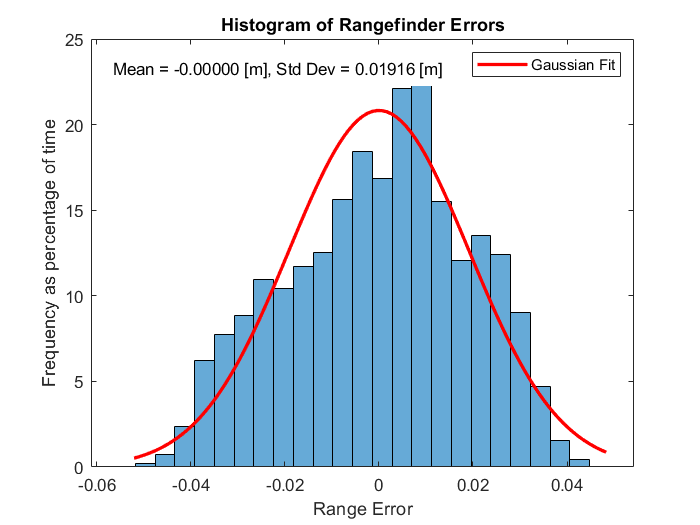

error_rangefinder = r - (l - x_true);
% Assuming 'error_rangefinder' is your data vector
data = error_rangefinder;
% Create the histogram
histogram(data, 25, 'Normalization', 'pdf'); % Normalizing to PDF to fit Gaussian
hold on;
% Fit a Gaussian (normal distribution) to the data
mu = mean(data);  % Mean of the data
sigma = std(data);  % Standard deviation of the data
% Create the x values for the Gaussian plot
x = linspace(min(data), max(data), 100);
% Plot the Gaussian
y = (1/(sigma*sqrt(2*pi))) * exp(-0.5 * ((x - mu)/sigma).^2);
gaussian_plot = plot(x, y, 'r-', 'LineWidth', 2);  % Plot the Gaussian in red
% Use 'annotation' instead of 'text' for more flexible positioning
dim = [0.15 0.8 0.3 0.1]; % Adjust as necessary [x y width height]
str = sprintf('Mean = %.5f [m], Std Dev = %.5f [m]', mu, sigma);
annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'none');
% Labels
title('Histogram of Rangefinder Errors');
xlabel('Range Error');
ylabel('Frequency as percentage of time');
% Show legend only for the Gaussian fit
legend(gaussian_plot, 'Gaussian Fit');
hold off;
% Save the plot
saveas(gcf, 'rangefinder_errors.png');

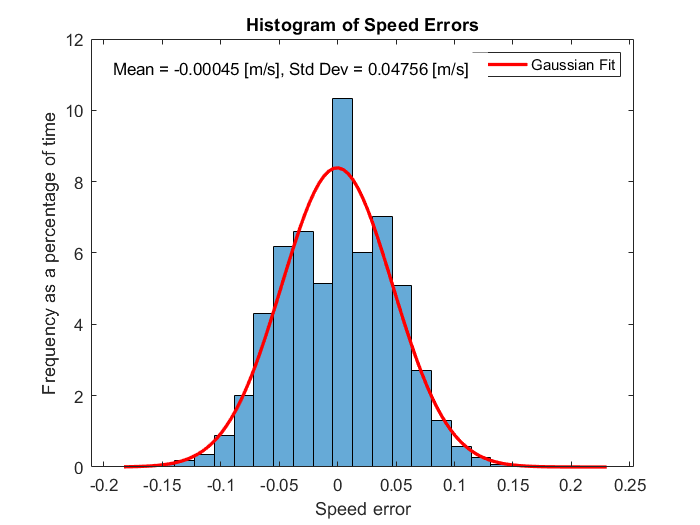

error_speed = v(2:end) - (x_true(2:end) - x_true(1:end-1)) ./ (t(2:end) - t(1:end-1));
% Assuming 'error_rangefinder' is your data vector
data = error_speed;
% Create the histogram
histogram(data, 25, 'Normalization', 'pdf'); % Normalizing to PDF to fit Gaussian
hold on;
% Fit a Gaussian (normal distribution) to the data
mu = mean(data);  % Mean of the data
sigma = std(data);  % Standard deviation of the data
% Create the x values for the Gaussian plot
x = linspace(min(data), max(data), 100);
% Plot the Gaussian
y = (1/(sigma*sqrt(2*pi))) * exp(-0.5 * ((x - mu)/sigma).^2);
gaussian_plot = plot(x, y, 'r-', 'LineWidth', 2);  % Plot the Gaussian in red
% Use 'annotation' instead of 'text' for more flexible positioning
dim = [0.15 0.8 0.3 0.1]; % Adjust as necessary [x y width height]
str = sprintf('Mean = %.5f [m/s], Std Dev = %.5f [m/s]', mu, sigma);
annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'none');
% Labels
title('Histogram of Speed Errors');
xlabel('Speed error');
ylabel('Frequency as a percentage of time');
% Show legend only for the Gaussian fit
legend(gaussian_plot, 'Gaussian Fit');
hold off;
% Save the plot
saveas(gcf, 'speed_errors.png');

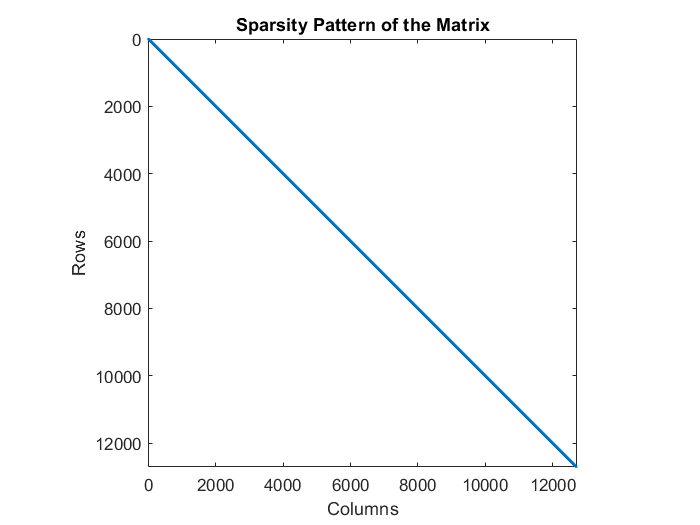

delta = 1;
sampling_period = t(2) - t(1);
dt = [t(2:end) - t(1:end-1); sampling_period];
x0 = 0.0; % Initial random state
P0 = 100.0; % Large to indicate uncertainty
% Full input velocity (vinp remains unchanged)
vinp = [x0; dt .* v];
% Full y vector (original measurements)
y0 = x0;
y = [y0; l - r];
% Downsample y by taking every delta-th measurement
y_downsampled = y(1:delta:end);
% Combine vinp and downsampled y
z = [vinp; y_downsampled];
% Adjust matrix dimensions based on the downsampled y
K_original = size(x_true, 1) + 1;  % Full size (original number of measurements)
K_downsampled = length(y_downsampled);  % New size after downsampling for y
% Recompute A and A_inv (these stay the same as before)
A = tril(ones(K_original, K_original));  % Lower triangular matrix
A_inv = speye(K_original) + spdiags(-ones(K_original-1, 1), -1, K_original, K_original);  % A_inv
% Update C matrix: it will have K_downsampled rows and K_original columns
C_downsampled = sparse(K_downsampled, K_original);
rows = 1:K_downsampled;
cols = 1:delta:(K_downsampled * delta);
C_downsampled(sub2ind(size(C_downsampled), rows, cols)) = 1;
% Update H matrix to account for downsampling only in y
H_downsampled = [A_inv; C_downsampled];  % Combine A_inv and new downsampled C
% Update Q matrix: same size as vinp, full size, no downsampling
Q = spdiags([1/P0; repmat(v_var, K_original-1, 1)], 0, K_original, K_original);  % No change for Q
% Update R matrix: only include downsampled measurements
R_downsampled = r_var * speye(K_downsampled);  % Reduced size for R
% Update W matrix: block diagonal with full Q and downsampled R
W_downsampled = blkdiag(Q, R_downsampled);  % Block diagonal sparse matrix W with downsampled R
answ = H_downsampled' * inv(W_downsampled) * H_downsampled;
% To visualize the sparsity pattern of the matrix
figure;  % Create a new figure
spy(answ);  % Plot the sparsity pattern
title('Sparsity Pattern of the Matrix');
xlabel('Columns');
ylabel('Rows');
% Save the figure as a PNG file
saveas(gcf, 'sparsity_LHS.png');

Shape of vinp: 12710 x 1
Shape of y (before downsampling): 12710 x 1
Shape of y (after downsampling): 12710 x 1
K_original (size of full measurement set): 12710
K_downsampled (size after downsampling): 12710
Shape of A: 12710 x 12710
Shape of A_inv: 12710 x 12710
Shape of C_downsampled: 12710 x 12710
Shape of H_downsampled: 25420 x 12710
Shape of Q: 12710 x 12710
Shape of R_downsampled: 12710 x 12710
Shape of W_downsampled: 25420 x 25420
Shape of P_hat: 12710 x 12710


x_hat =     0.9738
    0.9726
    0.9754
    0.9744
    0.9762
    0.9729
    0.9756
    0.9760
    0.9762
    0.9776


error =     0.0107
    0.0118
    0.0091
    0.0100
    0.0082
    0.0115
    0.0088
    0.0084
    0.0083
    0.0068


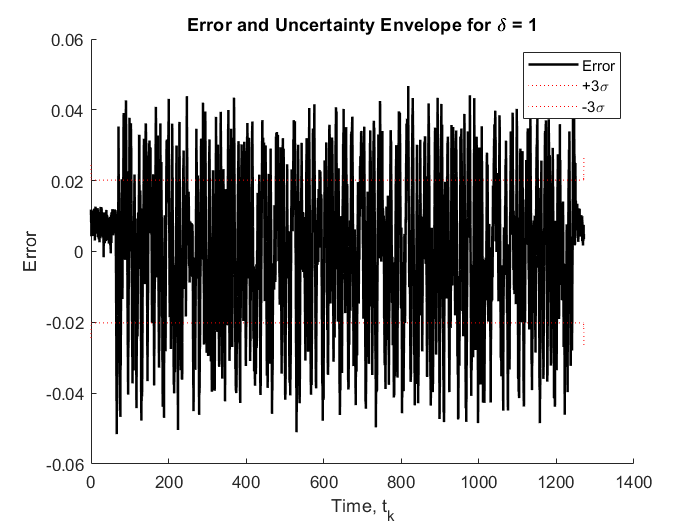

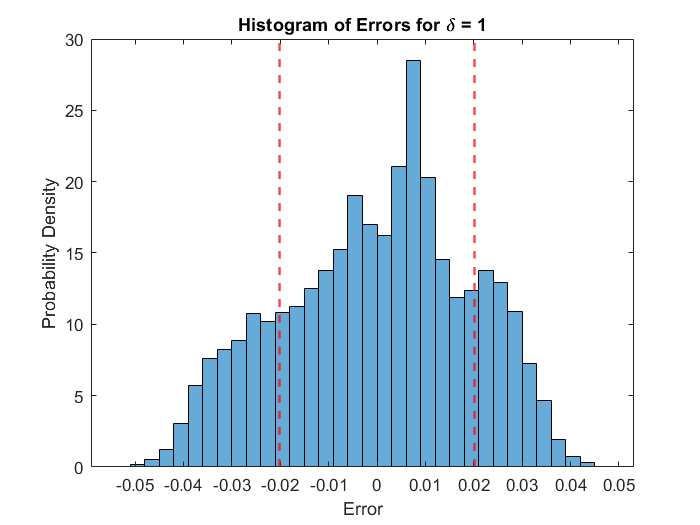

compute_solution_with_delta_cholesky(1, t, v, l, r, v_var, r_var, x_true)

Shape of vinp: 12710 x 1
Shape of y (before downsampling): 12710 x 1
Shape of y (after downsampling): 1271 x 1
K_original (size of full measurement set): 12710
K_downsampled (size after downsampling): 1271
Shape of A: 12710 x 12710
Shape of A_inv: 12710 x 12710
Shape of C_downsampled: 1271 x 12710
Shape of H_downsampled: 13981 x 12710
Shape of Q: 12710 x 12710
Shape of R_downsampled: 1271 x 1271
Shape of W_downsampled: 13981 x 13981
Shape of H_W_inv_H: 12710 x 12710
Shape of H_W_inv_z: 12710 x 1
Shape of P_hat: 12710 x 12710


error =     0.0087
    0.0085
    0.0085
    0.0083
    0.0082
    0.0081
    0.0080
    0.0079
    0.0078
    0.0076


uncertainty_upper =          (1,1)             0.0420
         (2,1)             0.0421
         (3,1)             0.0421
         (4,1)             0.0419
         (5,1)             0.0416
         (6,1)             0.0411
         (7,1)             0.0405
         (8,1)             0.0398
         (9,1)             0.0388
        (10,1)             0.0377
        (11,1)             0.0364
        (12,1)             0.0372
        (13,1)             0.0377
        (14,1)             0.0381
        (15,1)             0.0382
        (16,1)             0.0382
        (17,1)             0.0380
        (18,1)             0.0376
        (19,1)             0.0369
        (20,1)             0.0361
        (21,1)             0.0351
        (22,1)             0.0360
        (23,1)             0.0367
        (24,1)             0.0372
        (25,1)             0.0374
        (26,1)             0.0375
        (27,1)             0.0374
        (28,1)             0.0371
        (29,1)             0

uncertainty_lower =          (1,1)            -0.0420
         (2,1)            -0.0421
         (3,1)            -0.0421
         (4,1)            -0.0419
         (5,1)            -0.0416
         (6,1)            -0.0411
         (7,1)            -0.0405
         (8,1)            -0.0398
         (9,1)            -0.0388
        (10,1)            -0.0377
        (11,1)            -0.0364
        (12,1)            -0.0372
        (13,1)            -0.0377
        (14,1)            -0.0381
        (15,1)            -0.0382
        (16,1)            -0.0382
        (17,1)            -0.0380
        (18,1)            -0.0376
        (19,1)            -0.0369
        (20,1)            -0.0361
        (21,1)            -0.0351
        (22,1)            -0.0360
        (23,1)            -0.0367
        (24,1)            -0.0372
        (25,1)            -0.0374
        (26,1)            -0.0375
        (27,1)            -0.0374
        (28,1)            -0.0371
        (29,1)            -0

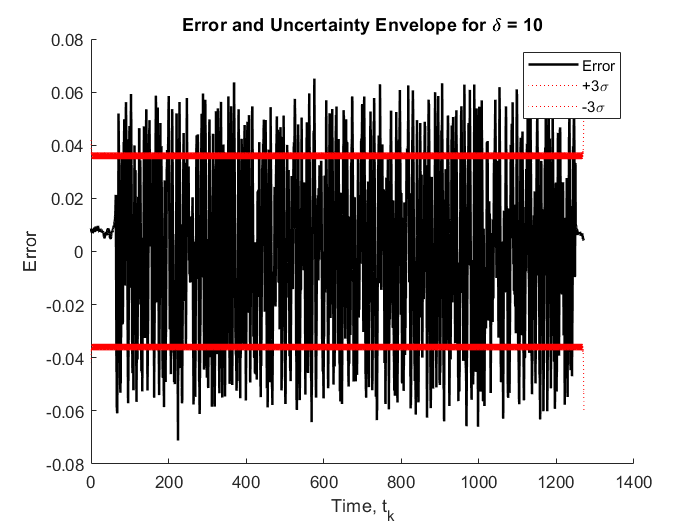

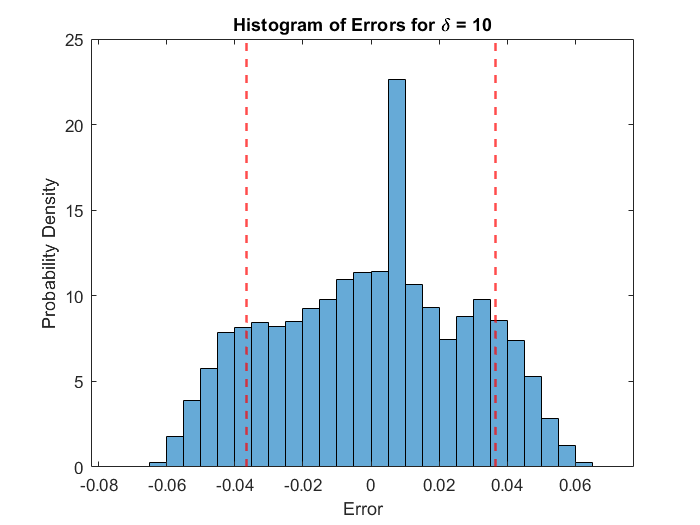

compute_solution_with_delta_easy(10, t, v, l, r, v_var, r_var, x_true)

Shape of vinp: 12710 x 1
Shape of y (before downsampling): 12710 x 1
Shape of y (after downsampling): 128 x 1
K_original (size of full measurement set): 12710
K_downsampled (size after downsampling): 128
Shape of A: 12710 x 12710
Shape of A_inv: 12710 x 12710
Shape of C_downsampled: 128 x 12710
Shape of H_downsampled: 12838 x 12710
Shape of Q: 12710 x 12710
Shape of R_downsampled: 128 x 128
Shape of W_downsampled: 12838 x 12838
Shape of H_W_inv_H: 12710 x 12710
Shape of H_W_inv_z: 12710 x 1
Shape of P_hat: 12710 x 12710


error =     0.0094
    0.0093
    0.0093
    0.0092
    0.0091
    0.0091
    0.0090
    0.0089
    0.0089
    0.0088


uncertainty_upper =          (1,1)             0.0538
         (2,1)             0.0552
         (3,1)             0.0565
         (4,1)             0.0578
         (5,1)             0.0590
         (6,1)             0.0601
         (7,1)             0.0613
         (8,1)             0.0623
         (9,1)             0.0634
        (10,1)             0.0644
        (11,1)             0.0653
        (12,1)             0.0662
        (13,1)             0.0671
        (14,1)             0.0679
        (15,1)             0.0687
        (16,1)             0.0695
        (17,1)             0.0703
        (18,1)             0.0710
        (19,1)             0.0717
        (20,1)             0.0723
        (21,1)             0.0730
        (22,1)             0.0736
        (23,1)             0.0742
        (24,1)             0.0747
        (25,1)             0.0752
        (26,1)             0.0758
        (27,1)             0.0762
        (28,1)             0.0767
        (29,1)             0

uncertainty_lower =          (1,1)            -0.0538
         (2,1)            -0.0552
         (3,1)            -0.0565
         (4,1)            -0.0578
         (5,1)            -0.0590
         (6,1)            -0.0601
         (7,1)            -0.0613
         (8,1)            -0.0623
         (9,1)            -0.0634
        (10,1)            -0.0644
        (11,1)            -0.0653
        (12,1)            -0.0662
        (13,1)            -0.0671
        (14,1)            -0.0679
        (15,1)            -0.0687
        (16,1)            -0.0695
        (17,1)            -0.0703
        (18,1)            -0.0710
        (19,1)            -0.0717
        (20,1)            -0.0723
        (21,1)            -0.0730
        (22,1)            -0.0736
        (23,1)            -0.0742
        (24,1)            -0.0747
        (25,1)            -0.0752
        (26,1)            -0.0758
        (27,1)            -0.0762
        (28,1)            -0.0767
        (29,1)            -0

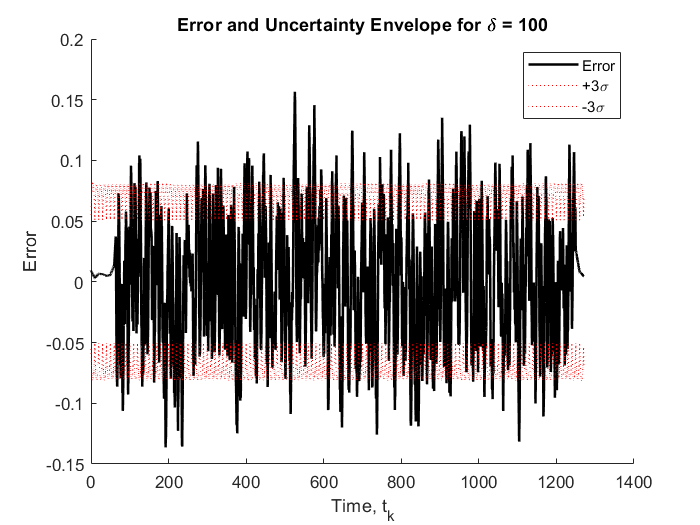

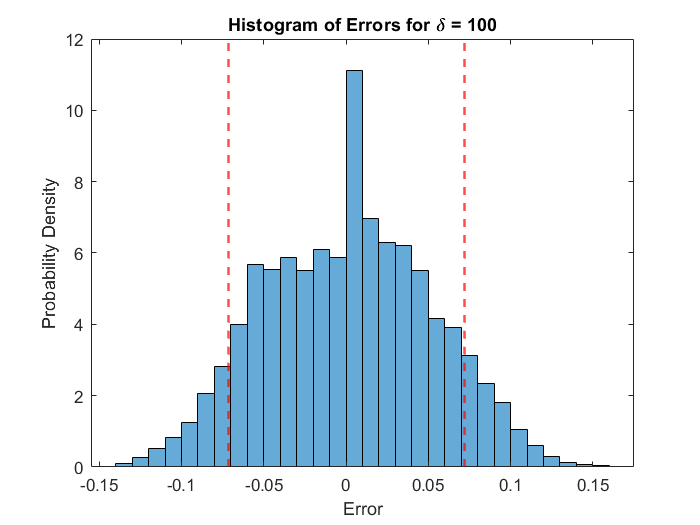

compute_solution_with_delta_easy(100, t, v, l, r, v_var, r_var, x_true)

Shape of vinp: 12710 x 1
Shape of y (before downsampling): 12710 x 1
Shape of y (after downsampling): 13 x 1
K_original (size of full measurement set): 12710
K_downsampled (size after downsampling): 13
Shape of A: 12710 x 12710
Shape of A_inv: 12710 x 12710
Shape of C_downsampled: 13 x 12710
Shape of H_downsampled: 12723 x 12710
Shape of Q: 12710 x 12710
Shape of R_downsampled: 13 x 13
Shape of W_downsampled: 12723 x 12723
Shape of H_W_inv_H: 12710 x 12710
Shape of H_W_inv_z: 12710 x 1
Shape of P_hat: 12710 x 12710


error =     0.0100
    0.0099
    0.0100
    0.0099
    0.0098
    0.0098
    0.0098
    0.0097
    0.0097
    0.0097


uncertainty_upper =          (1,1)             0.0570
         (2,1)             0.0587
         (3,1)             0.0604
         (4,1)             0.0620
         (5,1)             0.0635
         (6,1)             0.0650
         (7,1)             0.0665
         (8,1)             0.0680
         (9,1)             0.0694
        (10,1)             0.0708
        (11,1)             0.0721
        (12,1)             0.0734
        (13,1)             0.0747
        (14,1)             0.0760
        (15,1)             0.0773
        (16,1)             0.0785
        (17,1)             0.0797
        (18,1)             0.0809
        (19,1)             0.0821
        (20,1)             0.0832
        (21,1)             0.0843
        (22,1)             0.0855
        (23,1)             0.0866
        (24,1)             0.0876
        (25,1)             0.0887
        (26,1)             0.0898
        (27,1)             0.0908
        (28,1)             0.0918
        (29,1)             0

uncertainty_lower =          (1,1)            -0.0570
         (2,1)            -0.0587
         (3,1)            -0.0604
         (4,1)            -0.0620
         (5,1)            -0.0635
         (6,1)            -0.0650
         (7,1)            -0.0665
         (8,1)            -0.0680
         (9,1)            -0.0694
        (10,1)            -0.0708
        (11,1)            -0.0721
        (12,1)            -0.0734
        (13,1)            -0.0747
        (14,1)            -0.0760
        (15,1)            -0.0773
        (16,1)            -0.0785
        (17,1)            -0.0797
        (18,1)            -0.0809
        (19,1)            -0.0821
        (20,1)            -0.0832
        (21,1)            -0.0843
        (22,1)            -0.0855
        (23,1)            -0.0866
        (24,1)            -0.0876
        (25,1)            -0.0887
        (26,1)            -0.0898
        (27,1)            -0.0908
        (28,1)            -0.0918
        (29,1)            -0

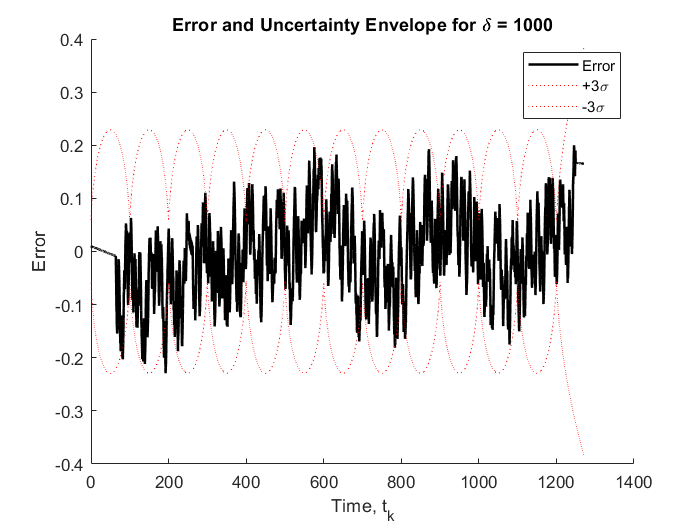

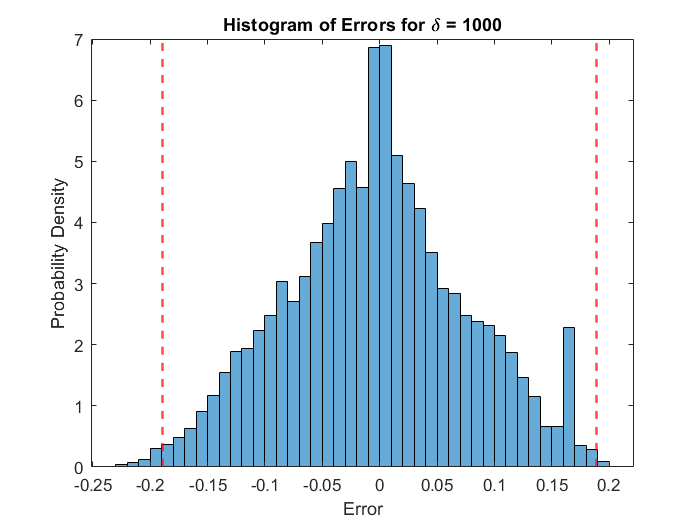

compute_solution_with_delta_easy(1000, t, v, l, r, v_var, r_var, x_true)

function compute_solution_with_delta_easy(delta, t, v, l, r, v_var, r_var, x_true)
    % Original sampling period and delta computations
    sampling_period = t(2) - t(1);
    dt = [t(2:end) - t(1:end-1); sampling_period];
    x0 = l-r(1); % Initial random state
    P0 = 10.0; % Large to indicate uncertainty

    % Full input velocity (vinp remains unchanged)
    vinp = [x0; dt .* v];

    % Full y vector (original measurements)
    y0 = x0;
    y = [y0; l - r];

    % Print shape of vinp and y
    fprintf('Shape of vinp: %d x %d\n', size(vinp));
    fprintf('Shape of y (before downsampling): %d x %d\n', size(y));

    % Downsample y by taking every delta-th measurement
    y_downsampled = y(1:delta:end);

    % Print shape of downsampled y
    fprintf('Shape of y (after downsampling): %d x %d\n', size(y_downsampled));

    % Combine vinp and downsampled y
    z = [vinp; y_downsampled];

    % Adjust matrix dimensions based on the downsampled y
    K_original = size(x_true, 1) + 1;  % Full size (original number of measurements)
    K_downsampled = length(y_downsampled);  % New size after downsampling for y

    % Print K_original and K_downsampled
    fprintf('K_original (size of full measurement set): %d\n', K_original);
    fprintf('K_downsampled (size after downsampling): %d\n', K_downsampled);

    % Recompute A and A_inv (these stay the same as before)
    A = tril(ones(K_original, K_original));  % Lower triangular matrix
    A_inv = speye(K_original) + spdiags(-ones(K_original-1, 1), -1, K_original, K_original);  % A_inv

    % Print shape of A and A_inv
    fprintf('Shape of A: %d x %d\n', size(A));
    fprintf('Shape of A_inv: %d x %d\n', size(A_inv));

    % Update C matrix: it will have K_downsampled rows and K_original columns
    C_downsampled = sparse(K_downsampled, K_original);
    rows = 1:K_downsampled;
    cols = 1:delta:(K_downsampled * delta);
    C_downsampled(sub2ind(size(C_downsampled), rows, cols)) = 1;

    % Print shape of C_downsampled
    fprintf('Shape of C_downsampled: %d x %d\n', size(C_downsampled));

    % Update H matrix to account for downsampling only in y
    H_downsampled = [A_inv; C_downsampled];  % Combine A_inv and new downsampled C

    % Print shape of H_downsampled
    fprintf('Shape of H_downsampled: %d x %d\n', size(H_downsampled));

    % Update Q matrix: same size as vinp, full size, no downsampling
    Q = spdiags([P0; repmat(v_var*sampling_period^2, K_original-1, 1)], 0, K_original, K_original);  % No change for Q

    % Print shape of Q
    fprintf('Shape of Q: %d x %d\n', size(Q));

    % Update R matrix: only include downsampled measurements
    R_downsampled = r_var * speye(K_downsampled);  % Reduced size for R

    % Print shape of R_downsampled
    fprintf('Shape of R_downsampled: %d x %d\n', size(R_downsampled));

    % Update W matrix: block diagonal with full Q and downsampled R
    W_downsampled = blkdiag(Q, R_downsampled);  % Block diagonal sparse matrix W with downsampled R

    % Print shape of W_downsampled
    fprintf('Shape of W_downsampled: %d x %d\n', size(W_downsampled));

    % Calculate H'*W^-1*H and H'*W^-1*z
    H_W_inv_H = H_downsampled' * inv(W_downsampled) * H_downsampled;
    H_W_inv_z = H_downsampled' * inv(W_downsampled) * z;

    % Print shape of H_W_inv_H and H_W_inv_z
    fprintf('Shape of H_W_inv_H: %d x %d\n', size(H_W_inv_H));
    fprintf('Shape of H_W_inv_z: %d x %d\n', size(H_W_inv_z));

    x_hat = H_W_inv_H \ H_W_inv_z;
    P_hat = inv(H_downsampled' * inv(W_downsampled) * H_downsampled);  % Finally compute the inverse of the result
    fprintf('Shape of P_hat: %d x %d\n', size(P_hat));
    x_hat = x_hat(2:end);  % Ignore the first element as it's only the initial state

    % Plot 1: Error and Uncertainty Envelope
    % Compute error: x_true - x_hat
    error = x_true - x_hat
    % Compute uncertainty envelope: ± 3 * sigma_xk
    sigma_xk = sqrt(diag(P_hat));  % Standard deviation from the variance
    uncertainty_upper = 3 * sigma_xk
    uncertainty_lower = -3 * sigma_xk

    % Plot the error and uncertainty envelope
    figure;
    hold on;
    % Plot the error as a solid line
    plot(t, error, 'k-', 'LineWidth', 1.5);  % Solid black line for error
    % Plot the uncertainty envelope as two dotted lines
    plot(t, uncertainty_upper(2:end), 'r:');  % Upper bound as a dotted red line
    plot(t, uncertainty_lower(2:end), 'r:');  % Lower bound as a dotted red line
    % Labels and title
    xlabel('Time, t_k');
    ylabel('Error');
    title(['Error and Uncertainty Envelope for \delta = ', num2str(delta)]);
    legend('Error', '+3\sigma', '-3\sigma');
    hold off;
    saveas(gcf, ['error_uncertainty_delta_' num2str(delta) '.png']);

    % Plot 2: Histogram of Errors
    figure;
    % Plot histogram of the errors
    histogram(error, 'Normalization', 'pdf');  % Normalized to show PDF
    % Labels and title
    xlabel('Error');
    ylabel('Probability Density');
    title(['Histogram of Errors for \delta = ', num2str(delta)]);
    % Overlay predicted uncertainty (±3 sigma range) using a vertical line
    hold on;
    sigma_xk_mean = mean(sqrt(diag(P_hat)));  % Mean standard deviation
    xline(3 * sigma_xk_mean, 'r--', 'LineWidth', 1.5);  % +3 sigma line
    xline(-3 * sigma_xk_mean, 'r--', 'LineWidth', 1.5);  % -3 sigma line
    hold off;
    saveas(gcf, ['histogram_error_delta_' num2str(delta) '.png']);
end

function compute_solution_with_delta_cholesky(delta, t, v, l, r, v_var, r_var, x_true)
    % Original sampling period and delta computations
    sampling_period = t(2) - t(1);
    dt = [t(2:end) - t(1:end-1); sampling_period];
    x0 = l-r(1); % Initial random state
    P0 = 10.0; % Large to indicate uncertainty

    % Full input velocity (vinp remains unchanged)
    vinp = [x0; dt .* v];

    % Full y vector (original measurements)
    y0 = x0;
    y = [y0; l - r];

    % Print shape of vinp and y
    fprintf('Shape of vinp: %d x %d\n', size(vinp));
    fprintf('Shape of y (before downsampling): %d x %d\n', size(y));

    % Downsample y by taking every delta-th measurement
    y_downsampled = y(1:delta:end);

    % Print shape of downsampled y
    fprintf('Shape of y (after downsampling): %d x %d\n', size(y_downsampled));

    % Combine vinp and downsampled y
    z = [vinp; y_downsampled];

    % Adjust matrix dimensions based on the downsampled y
    K_original = size(x_true, 1) + 1;  % Full size (original number of measurements)
    K_downsampled = length(y_downsampled);  % New size after downsampling for y

    % Print K_original and K_downsampled
    fprintf('K_original (size of full measurement set): %d\n', K_original);
    fprintf('K_downsampled (size after downsampling): %d\n', K_downsampled);

    % Recompute A and A_inv (these stay the same as before)
    A = tril(ones(K_original, K_original));  % Lower triangular matrix
    A_inv = speye(K_original) + spdiags(-ones(K_original-1, 1), -1, K_original, K_original);  % A_inv

    % Print shape of A and A_inv
    fprintf('Shape of A: %d x %d\n', size(A));
    fprintf('Shape of A_inv: %d x %d\n', size(A_inv));

    % Update C matrix: it will have K_downsampled rows and K_original columns
    C_downsampled = sparse(K_downsampled, K_original);
    rows = 1:K_downsampled;
    cols = 1:delta:(K_downsampled * delta);
    C_downsampled(sub2ind(size(C_downsampled), rows, cols)) = 1;

    % Print shape of C_downsampled
    fprintf('Shape of C_downsampled: %d x %d\n', size(C_downsampled));

    % Update H matrix to account for downsampling only in y
    H_downsampled = [A_inv; C_downsampled];  % Combine A_inv and new downsampled C

    % Print shape of H_downsampled
    fprintf('Shape of H_downsampled: %d x %d\n', size(H_downsampled));

    % Update Q matrix: same size as vinp, full size, no downsampling
    Q = spdiags([P0; repmat(v_var*sampling_period^2, K_original-1, 1)], 0, K_original, K_original);  % No change for Q

    % Print shape of Q
    fprintf('Shape of Q: %d x %d\n', size(Q));

    % Update R matrix: only include downsampled measurements
    R_downsampled = r_var * speye(K_downsampled);  % Reduced size for R

    % Print shape of R_downsampled
    fprintf('Shape of R_downsampled: %d x %d\n', size(R_downsampled));

    % Update W matrix: block diagonal with full Q and downsampled R
    W_downsampled = blkdiag(Q, R_downsampled);  % Block diagonal sparse matrix W with downsampled R

    % Print shape of W_downsampled
    fprintf('Shape of W_downsampled: %d x %d\n', size(W_downsampled));

    x_hat = cholesky_forward_backward(P0, v_var, r_var, x0, vinp, y_downsampled, K_original);

    P_hat = inv(H_downsampled' * inv(W_downsampled) * H_downsampled);  % Finally compute the inverse of the result
    fprintf('Shape of P_hat: %d x %d\n', size(P_hat));
    x_hat = x_hat(2:end)  % Ignore the first element as it's only the initial state

    % Plot 1: Error and Uncertainty Envelope
    % Compute error: x_true - x_hat
    error = x_true - x_hat
    % Compute uncertainty envelope: ± 3 * sigma_xk
    sigma_xk = sqrt(diag(P_hat));  % Standard deviation from the variance
    uncertainty_upper = 3 * sigma_xk;
    uncertainty_lower = -3 * sigma_xk;

    % Plot the error and uncertainty envelope
    figure;
    hold on;
    % Plot the error as a solid line
    plot(t, error, 'k-', 'LineWidth', 1.5);  % Solid black line for error
    % Plot the uncertainty envelope as two dotted lines
    plot(t, uncertainty_upper(2:end), 'r:');  % Upper bound as a dotted red line
    plot(t, uncertainty_lower(2:end), 'r:');  % Lower bound as a dotted red line
    % Labels and title
    xlabel('Time, t_k');
    ylabel('Error');
    title(['Error and Uncertainty Envelope for \delta = ', num2str(delta)]);
    legend('Error', '+3\sigma', '-3\sigma');
    hold off;
    saveas(gcf, ['error_uncertainty_delta_' num2str(delta) '.png']);

    % Plot 2: Histogram of Errors
    figure;
    % Plot histogram of the errors
    histogram(error, 'Normalization', 'pdf');  % Normalized to show PDF
    % Labels and title
    xlabel('Error');
    ylabel('Probability Density');
    title(['Histogram of Errors for \delta = ', num2str(delta)]);
    % Overlay predicted uncertainty (±3 sigma range) using a vertical line
    hold on;
    sigma_xk_mean = mean(sqrt(diag(P_hat)));  % Mean standard deviation
    xline(3 * sigma_xk_mean, 'r--', 'LineWidth', 1.5);  % +3 sigma line
    xline(-3 * sigma_xk_mean, 'r--', 'LineWidth', 1.5);  % -3 sigma line
    hold off;
    saveas(gcf, ['histogram_error_delta_' num2str(delta) '.png']);
end

function x_hat = cholesky_forward_backward(P0, v_var, r_var, x0, vinp, y_downsampled, K)
    % Function to estimate x_hat using Cholesky forward and backward pass with delta
    
    % Initialization based on problem description
    Ak = 1;  % Process model coefficient (constant 1 in your case)
    Ck = 1;  % Measurement model coefficient (constant 1 in your case)

    % Initial covariance and gain values
    P0_inv = 1 / P0;  % Inverse of initial covariance
    Rk_inv = 1 / r_var;  % Inverse of measurement noise covariance
    Qk_inv = 1 / v_var;  % Inverse of process noise covariance
    
    % Initial values for forward pass
    I0 = P0_inv + Ck' * Rk_inv * Ck;  % Initialization for I_0
    q0 = P0_inv * x0 + Ck' * Rk_inv * y_downsampled(1);  % Initialization for q_0

    % Preallocate L_k (main diagonal), L_km1_k (subdiagonal), qk, and Ik
    L_k = zeros(K, 1);      % Main diagonal elements of L
    L_k_km1 = zeros(K-1, 1); % Subdiagonal elements of L
    qk = zeros(K, 1);        % q values
    Ik = zeros(K, 1);        % I values
    d = zeros(K, 1);

    % Set initial values for I and q
    Ik(1) = I0;
    qk(1) = q0;

    % Cholesky forward pass
    for k = 2:K
        L_k(k-1) = sqrt(Ik(k-1) + Ak' * Qk_inv * Ak);
        d(k-1) = (qk(k-1) - Ak' * Qk_inv * vinp(k)) / L_k(k-1);
        L_k_km1(k-1) = -Qk_inv * Ak / L_k(k-1)';
        Ik(k) = -(L_k_km1(k-1))^2 + Qk_inv + Ck' * Rk_inv * Ck;  % I_k = L_k * L_k^T
        qk(k) = -L_k_km1(k-1) * d(k-1) + Qk_inv * vinp(k) + Ck' * Rk_inv * y_downsampled(k);
    end

    L_k(K) = sqrt(Ik(K));
    d(K) = qk(K) / L_k(K);

    % Cholesky backward pass
    x_hat = zeros(K, 1);
    x_hat(K) = d(K) / L_k(K);

    for k = K-1:-1:1
        x_hat(k) = (d(k) - L_k_km1(k) * x_hat(k+1)) / L_k(k);
    end
end